# Tank level and PI control 

This livescript is a brief manual in support of the app ***tanklevel_and_PIcontrol.mlapp***.   This is a simple interface to build on the earlier file ***tanklevelbehaviour.mlapp***  which focussed on understanding the modelling and behaviour of simple tank level models, subject to changes in the core parameters such as tank volume, flow rate,  disturbances to the inlet flow and blockages in the outlet pipe. 

This file moves onto the next aspect which is, how do we ensure we have the desired level, irrespective of the unnknown disturbances and changes in system parameters? These notes give the engineering and analytical background alongside some simple MATLAB code snippets than can be used for equivalent analysis.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Context of the tank system

- Closed-loop step response computation and display

- Impact of intermittent blockages

-  Interface and user interaction of the app file

## 1. Context of the tank level system and requirements

The figure below shows the maximum extent of the tank dimensions, so a width of upto 10 and a depth of 9. 

- The width/area can be modified by the user. 

- The water exits the tank from the outlet in the bottom right which has variable dimensions (linked to a conductance term *R*), again adjustable by the user. 

- The red rectangle represents a plug or bung which, from time to time moves down and acts as a blockage on the outlet pipe thus reducing its area and  the corresponding outflow. The user can also vary the percentage overlap of this bung with the outlet.

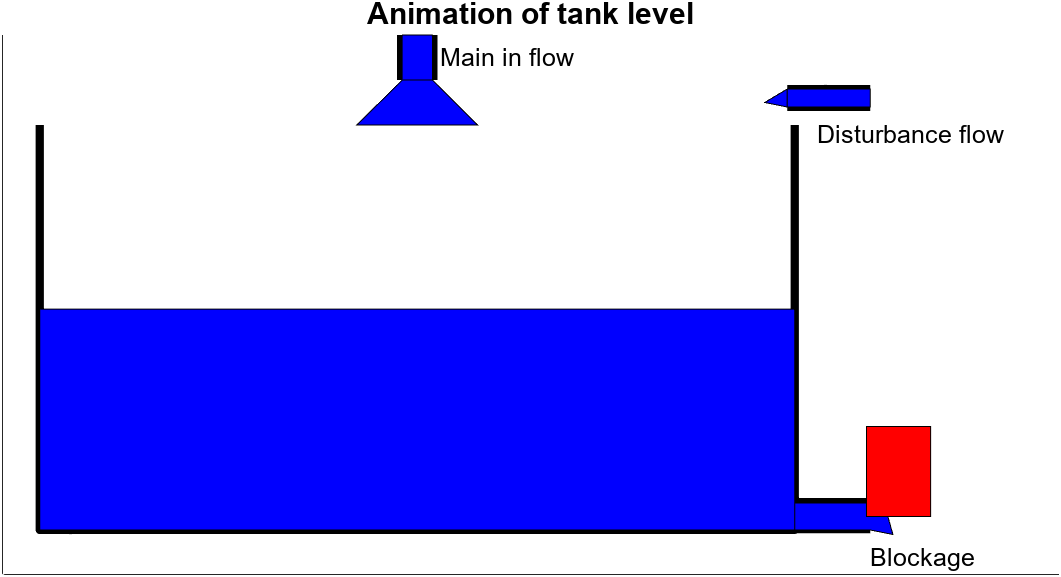

There are two input flows:

- the flow in the top centre is a controllable flow which the user adjusts to achieve the desired depth. This flow could be selected via open-loop or closed-loop mechanisms.

- the flow on the top right is a disturbance flow which again can be varied by the user. 

### 1.1 Model of the tank system

Assume cross-sectional area *A* and that the flow out is dependent on the depth *h* through a conductance parameter *R*. Then, using a volume balance the equation for the depth is governed by;


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}} ;\;\;\;\;f_{\textrm{in}} =f+d;\;\;\;\;\;\;\equiv \;\;\;\;\;\;G\left(s\right)=\frac{1}{\textrm{As}+R}$$


where the flow in comprises the two components: *f* for controllable flow and *d* for disturbance flow. Blockage of the outlet pipe reduces the value of parameter *R*. A simple model for the tank behaviour is derived using the time constant form below (assuming constant in flows). 

$\frac{A}{R}\frac{\textrm{dh}}{\textrm{dt}}+h=\frac{1}{R}\left(f+d\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;T=\frac{A}{R},\;\;\textrm{Gain}=\frac{1}{R}$; 

$h\left(t\right)=$$\frac{1}{R}\left(f+d\right)-$$\left(h\left(0\right)-\frac{1}{R}\left(f+d\right)\right)$$e^{-\frac{t}{T}}$;           $h_{\textrm{ss}} =\frac{f+d}{R}$

where $h_{\textrm{ss}}$ is the steady-state depth.

### 1.2 Uncertainties

There are two main uncertainties which impact on the level in the tank.

The disturbance flow d has an obvious effect on the steady-state in that a change in disturbance flow leads to a change in the steady-state depth as follows: $\delta h_{\textrm{ss}} =\frac{d}{R}$

A blockage (denoted as a fraction between 0 and 1) impacts on the conductance term* R and thus* it impacts on both the steady-state and the time constant.

$T=\frac{A}{R\left(1-B\right)},\;\;\textrm{Gain}=\frac{1}{R\left(1-B\right)}$; ${\;\;\;\;\;\;\;\;h}_{\textrm{ss}} =\frac{f+d}{R\left(1-B\right)}$

Hence an increase in the blockage term *B* causes an increase in the steady-state and an increase in the time constant. Note in this case the transfer function model would become:

$G\left(s\right)=\frac{\textrm{Gain}}{\textrm{Ts}+1}$ where  notionally   $h\left(s\right)=G\left(s\right)\left\lbrack f\left(s\right)+d\left(s\right)\right\rbrack$

### 1.3 Performance requirements

The performance requirement is set quite simply as, get the tank to a desired target depth ***H***. For simplicitly the app mostly has this level as a fixed value of ***H=8*** (defined in the preliminary section of the mlapp file so it can be changed).  One exception is the part which looks at deviation about steady-state during intermittement blockages; in this case the desired level is set as ***H=4*** to avoid distracting overflows.

Users can experiment with PI design and also the impact on the design efficacy of both parameter changes (*A* and *R*) and also disturbances and blockages.

### 1.4 PI design 

We wish to control the depth in the tank to the target ***H*** by moving the in-flow. To do this a PI compensator is used :


$$f\left(s\right)=\left(K_p +\frac{K_i }{s}\right)\left(H\left(s\right)-h\left(s\right)\right)=C\left(s\right)\left(H\left(s\right)-h\left(s\right)\right)$$


Standard control threory will tell readers that including the integral will ensure offset free tracking in the steady-state, and because the model is first order, stability is assured. However, we still need to determine sensible values for the compensator coefficients.

Users can explore the impact of changing the two PI parameters on closed-loop behaviour and the performance requirements.

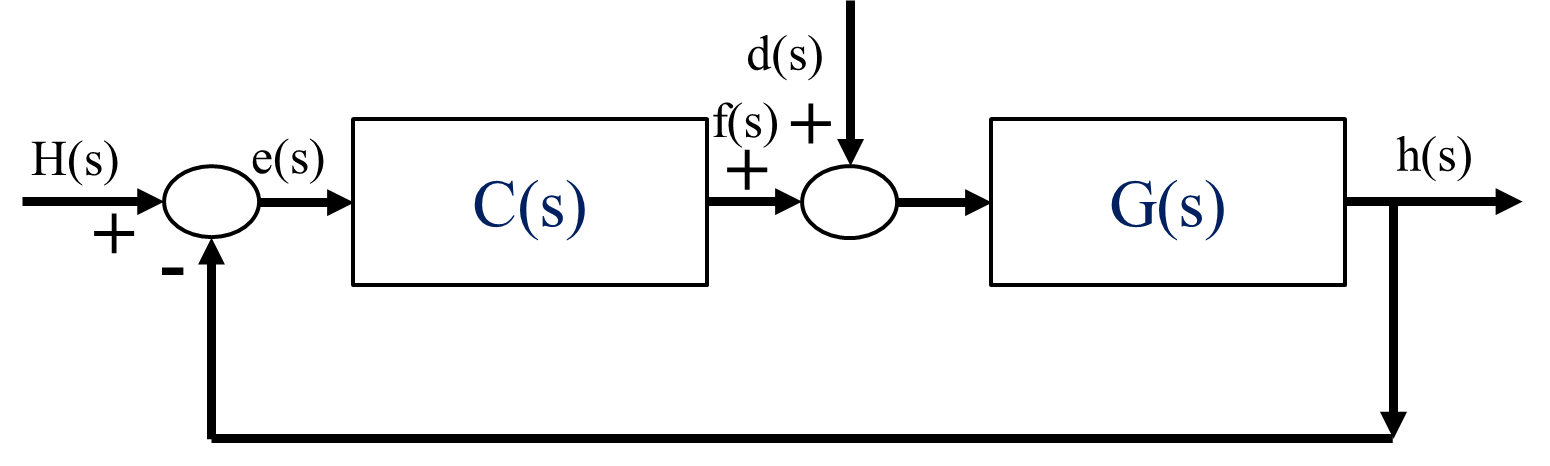

### 1.5. Closed-loop behaviour analysis

The closed-loop transferences for the block diagram above can be summarised as:

$Y_r \left(s\right)=G_c \left(s\right)H\left(s\right)$ with   $G_c =\frac{\textrm{GC}}{1+\textrm{GC}}$         Dependence of depth on the target.

$U_r \left(s\right)=G_{\textrm{cu}} \left(s\right)H\left(s\right)$ with   $G_{\textrm{cu}} =\frac{C}{1+\textrm{GC}}$    Dependence of flow-in term on the target.

$Y_d \left(s\right)=G_{\textrm{cd}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cd}} =\frac{G}{1+\textrm{GC}}$    Dependence of depth on the disturbance flow.

$U_d \left(s\right)=G_{\textrm{cud}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cud}} =\frac{-\textrm{GC}}{1+\textrm{GC}}$    Dependence of in-flow* f * on the disturbance flow *d*.

The total depth and in-flow is computed from superposition, hence:


$$h=Y_r +Y_d ;\;\;\;f=U_r +U_d$$


## 2. Using the app to validate expectations of closed-loop behaviour

The app will compute all the closed-loop transfer functions from section 1.5 and then plot the corresponding behaviour. Consequently, users can compare and contrast the behaviours for different simulation choices such as model parameters, PI parameters and disturbances.

We illustrate some of the code below for convenience. For simplicity one can use Laplace transforms and step.m to form the generic open-loop model and the corresponding step response.

Users can change the parameter definitions, for example on lines 2 and 5 below, in order to generate graphs for different scenarios.

% Define parameters
A = 5; R = 0.1; B = 0;  Rblock = R*(1-B);
G=tf(1,[A,R]);    % tank model
Gb=tf(1,[A,Rblock]);  % with blockage
Kp=0.1; Ki=0.01;
PI=tf([Kp,Ki],[1 0]);

% find closed-loop transfer functions
% no blockage
Gc = feedback(G*PI,1); % target to depth
Gcd = feedback(G,PI);  % disturbance to depth
Gcu = feedback(PI,G);  % target to in-flow
Gcud = -Gc;% disturbance to in-flow
% with blockage
Gcb = feedback(Gb*PI,1); % target to depth
Gcdb = feedback(Gb,PI);  % disturbance to depth
Gcub = feedback(PI,Gb);  % target to in-flow
Gcudb = - Gcb;% disturbance to in-flow
            
% find closed-loop unit step responses
time = linspace(0,150,201);
[h]=step(Gc,time);    
[u]=step(Gcu,time);   
[hd]=step(Gcd,time);  
[ud]=step(Gcud,time); 
[hb]=step(Gcb,time);    
[ub]=step(Gcub,time);   
[hdb]=step(Gcdb,time);  
[udb]=step(Gcudb,time); 

Using superposition of the response above, one can determine the behaviour for different scenarios such as:

- Simple change in the target depth.

- Change in the target depth, while subject to a disturbance flow.

- Change in the target depth while the system experiences an outlet pipe partial blockage.

Some example code is given here.

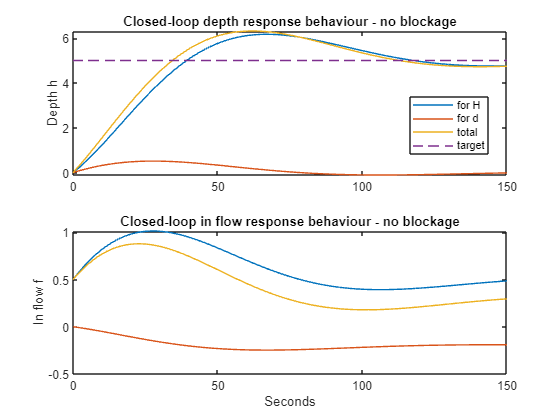

% Plot behaviour for known target and disturbance in flow
H=5; d=0.2;

figure
subplot(211)
plot(time,h*H,time,hd*d,time,(h*H+hd*d),[time(1),time(end)],[H,H],'--')
legend('for H','for d','total','target')
ylabel('Depth h')
title('Closed-loop depth response behaviour - no blockage')

subplot(212)
plot(time,u*H,time,ud*d,time,(u*H+ud*d))
title('Closed-loop in-flow response behaviour - no blockage')
ylabel('In flow f')
xlabel('Seconds')

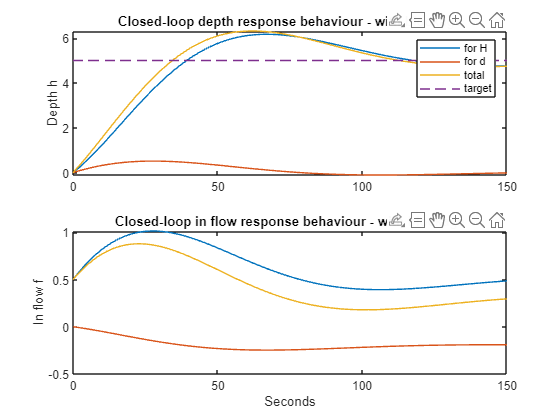


figure
subplot(211)
plot(time,hb*H,time,hdb*d,time,(hb*H+hdb*d),[time(1),time(end)],[H,H],'--')
legend('for H','for d','total','target')
ylabel('Depth h')
title('Closed-loop depth response behaviour - with blockage')

subplot(212)
plot(time,ub*H,time,udb*d,time,(ub*H+udb*d))
title('Closed-loop in flow response behaviour - with blockage')
ylabel('In flow f')

xlabel('Seconds')

## **3. The impact of intermittent blockages**

While a permanent blockage effects the system dynamics and behaviour in an ongoing fashion, an equally likely scenario is where there is a temporary blockage and thus temporary change in dynamics. It is interesting to see how well the PI compensator deals with this.

In terms of coding, it is efficient to go back to first principles ODEs and Laplace transforms in order to generate analytic solutions which depend upon the initial conditions and can then be illustrated. For simplicitly assume the system begins from a steady-state position and also that the disturbance in-flow is zero as the disturbance in-flow has no impact on the main observations.

**Initial conditions: **Assume the initial condition or steady-state is before the blockage, and therefore the steady-state values are:

  $h_{\textrm{ss}} =\frac{f}{R}=H$;  $f_{\textrm{ss}} =\textrm{HR}$

Therefore one can assume that:     $h\left(0\right)=h_{\textrm{ss}} \ldotp$

The PI compensator has an output:  $f\left(s\right)=\left(K_p +\frac{K_i }{s}\right)\left(H\left(s\right)-h\left(s\right)\right)$, and assuming zero offset at initialisation, one can determine that the integral of error term $e_{\int }$ at initialisation obeys the equation:       $e_{\int } \left(0\right)K_i =f_{\textrm{ss}}$.

**Going forward in time**: We can take Laplace transforms of the system model (now including the blockage) and PI compensator using the supplied initial conditions. So:


$$\textrm{Ash}\left(s\right)-\textrm{Ah}\left(0\right)+R\left(1-B\right)h\left(s\right)=f\left(s\right)\Rightarrow h\left(s\right)=\frac{1}{\textrm{As}+R\left(1-B\right)}\left(f\left(s\right)+\textrm{Ah}\left(0\right)\right)=G\left(s\right)f\left(s\right)+P\left(s\right)h\left(0\right)$$



$$f\left(s\right)=\left(K_p +\frac{K_i }{s}\right)\left(H\left(s\right)-h\left(s\right)\right)+\frac{f_{\textrm{ss}} }{s}=C\left(s\right)\left(H\left(s\right)-h\left(s\right)\right)+\frac{f_{\textrm{ss}} }{s}$$


**Defining analytic solutions:** These two equations can be solved simultaneously to provide solutions for both depth and in-flow.


$$\begin{array}{l}
h\left(s\right)=G\left(s\right)\left\lbrack C\left(s\right)\left(H\left(s\right)-h\left(s\right)\right)+\frac{f_{\textrm{ss}} }{s}\right\rbrack +P\left(s\right)h\left(0\right)\;\Rightarrow \\
h\left(s\right)=\left\lbrack \frac{\textrm{GC}}{1+\textrm{GC}}\right\rbrack H+\left\lbrack \frac{G}{1+\textrm{GC}}\right\rbrack \frac{f_{\textrm{ss}} }{s}+\left\lbrack \frac{P}{1+\textrm{GC}}\right\rbrack h\left(0\right)
\end{array}$$



$$f\left(s\right)=\left\lbrack \frac{C}{1+\textrm{GC}}\right\rbrack H+\left\lbrack \frac{1}{1+\textrm{GC}}\right\rbrack \frac{f_{\textrm{ss}} }{s}-\left\lbrack \frac{\textrm{CP}}{1+\textrm{GC}}\right\rbrack h\left(0\right)$$


disp('Section 3 below here')

Section 3 below here


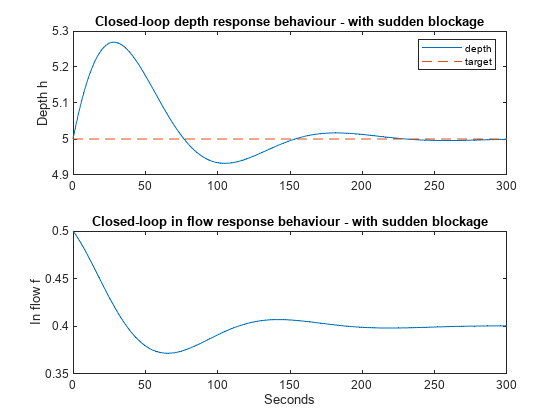


% Define parameters
A = 5; R = 0.1; B = 0.2;  Rblock = R*(1-B);
G=tf(1,[A,R]);    % tank model
Gb=tf(1,[A,Rblock]);  % with blockage
Kp=0.1; Ki=0.01; H = 5;
PI=tf([Kp,Ki],[1 0]);
P = tf(A,[A,Rblock]);
h0 = H; fss = H*R;

% Closed-loop
Gc = feedback(Gb*PI,1); % target to depth
Gci = feedback(Gb,PI);  % initial input to depth
Gch = feedback(1,Gb*PI)*P; % initial depth to final depth
Gcu = feedback(PI,Gb);  % target to in-flow
Gcui = feedback(1,Gb*PI);% initial input to in-flow
Gcuh = -feedback(PI,Gb)*P; % initial depth to flow

% time behaviour
time = linspace(0,300,201);
h = step(Gc,time); h = h*H;
hi = step(Gci,time); hi = hi*fss;
hh = impulse(Gch,time); hh = hh*h0;
u = step(Gcu,time); u = u*H;
ui = step(Gcui,time); ui = ui*fss;
uh = impulse(Gcuh,time); uh = uh*h0;

% Plotting
figure
subplot(211)
plot(time,h+hi+hh,[time(1),time(end)],[H,H],'--')
legend('depth','target')
ylabel('Depth h')
title('Closed-loop depth response behaviour - with sudden blockage')

subplot(212)
plot(time,u+ui+uh)
title('Closed-loop in flow response behaviour - with sudden blockage')
ylabel('In flow f')

xlabel('Seconds')

## **4. **Interface and user interaction of the app file

The user can change 5 parameters (Area, conductance, flow-in, disturbance flow and blockage percentage) and thus investigate easily the impact of changes. The parameters can only take a finite number of discrete values, as on the sliders, to avoid excessive decimal places. The drop-down menu at the bottom also allows the disturbance to be applied throughout, or introduced mid-simulation and also the investigation of intermittent blockages; for the top two the target depth is taken to be 8 while for the latter case a value of 4 is used (denoted by the dashed green lines).

- The top figure shows the tank and inlet/outlet pipes. The dimensions of these change to reflect volume,  in-flow rate, disturbance flow and any blockage of the outlet pipe. 

- The middle right figure overlays the depth responses for all recent choices so the comparison is easy to view.

- The bottom right figure overlays the in-flow response for all the recent choices.

The app will overlay all recent responses so the comparison is clear - simulations run for about 5 time constants, so are parameter choice dependent. The legend keeps track of key parameter choices not obvious from the graph. To refresh and begin again, use the refresh button.

You can disable the animation to see quicker responses using the 'animation on/off' button.